## 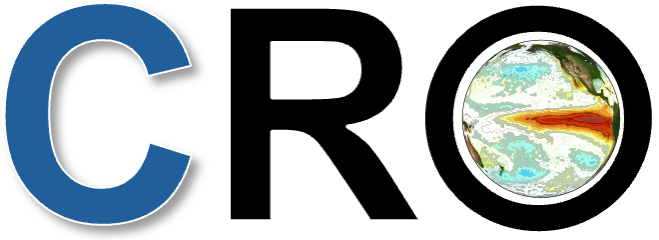

## **Community Recharge Oscillator (CRO) v0.0 for MATLAB**

## **1. RO Master Equations**

- 
$$\frac{dT}{dt} = RT + F_{1}h + b_{T}T^{2} - c_{T}T^{3} + d_{T}Th + \sigma_{T}N_{T}(1+g_{T})+E_{T}$$


- 
$$\frac{dh}{dt} = -\varepsilon{h} - F_{2}T - b_{h}T^{2} + \sigma_{h}N_{h}+E_{h}$$


- 
$$\frac{d\xi_T}{dt} = -m_T \xi_T + \sqrt{2 m_T} w_T$$


- 
$$\frac{d\xi_h}{dt} = -m_h \xi_h + \sqrt{2 m_h} w_h$$


- 
$$N_T = \left\{\begin{array}{ll}\xi_T, & \textrm{if } n_T = 0 \quad \textrm{(red noise)} \\w_T, & \textrm{if } n_T = 1 \quad \textrm{(white noise)}\end{array}\right.$$


- 
$$N_h = \left\{\begin{array}{ll}\xi_h, & \textrm{if } n_h = 0 \quad \textrm{(red noise)} \\w_h, & \textrm{if } n_h = 1 \quad \textrm{(white noise)}\end{array}\right.$$


- 
$$g_T = \left\{\begin{array}{ll}B \cdot T, & \textrm{if } n_g = 0 \quad \textrm{(linear multiplicative noise)} \\B \cdot H(T) \cdot T, & \textrm{if } n_g = 1 \quad \textrm{(Heaviside-based multiplicative noise)} \\0 & \textrm{if } n_g = 2 \quad \textrm{(additive noise)}\end{array}\right.$$


- $T$ (K) and $h$ (m) represent the monthly sea surface temperature (SST) and thermocline depth anomalies, respectively.

- $w_T$ and $w_h$ are uncorrelated Gaussian white noise forcings with zero mean and unit variance, applied to the $T$ and $h$ equations, respectively.

- $E_T$ and $E_h$ are external forcings applied to the $T$ and $h$ equations, respectively.

- The physical meaning and units of each parameter will be provided in the final version. 

**Linear and Nonlinear Parameters**

$R$ (`R`), $F_1$ (`F1`), $F_2$ (`F2`), $\epsilon$ (`epsilon`), $b_T$ (`b_T`), $c_T$ (`c_T`), $d_T$ (`d_T`), $b_h$ (`b_h`)

- `'parameter': []` → interpreted as zero (e.g., `'R': []` is the same as `'R': [0.0]`)

- `'parameter': [value]` → only the annual mean is used (e.g., `'R': [-0.05]` means the annual mean value of –0.05 is used for R)

- `'parameter': [mean, amplitude, phase (in radians)]` → annual mean and annual seasonality are used (e.g., `'R': [-0.05, 0.05, np.pi]` means R has an annual mean of –0.05 and a seasonal variation with amplitude 0.05 and phase shift ππ)

- `'parameter': [mean, amp₁, phase₁ (in radians), amp₂, phase₂ (in radians)]` → annual mean, annual seasonality, and semi-annual seasonality are used (e.g., `'R': [-0.05, 0.05, np.pi, 0.01, np.pi/2]` means R has an annual mean of –0.05, annual amplitude 0.05 with phase ππ, and semi-annual amplitude 0.01 with phase π/2π/2)

- Any other form → **invalid** (e.g., `'parameter': [mean, amp]` will raise an error) 

**Noise Parameters**

$\sigma_T$(`sigma_T`), $\sigma_h$(`sigma_h`), $B$ (`B`), $m_T$ (`m_T`), $m_h$ (`m_h`)

- These follow the same format as the linear and nonlinear parameters, meaning that **seasonality can be included for RO simulations**.

- However, **RO parameter fitting does not support seasonality** in these parameters. Therefore, it is strongly recommended to use **annual means only** for consistency during RO fitting.

**Noise Option Parameters**

$n_T$ (`n_T`), $n_h$ (`n_h`), $n_g$ (`n_g`)

- `n_T` and `n_h` are flags that specify the noise type for the TT and hh equations, respectively:

- `0`: red noise

- `1`: white noise

- `n_g` is a flag for the **multiplicative noise type** in the TT equation:

- `0`: linear multiplicative noise (1+B⋅T)(1+B⋅T)

- `1`: Heaviside-based multiplicative noise (1+B⋅H(T)⋅T)(1+B⋅H(T)⋅T)

- `2`: no multiplicative noise (i.e., additive only) 

- `'parameter': [integer]` or `'parameter': integer` is a valid option; any other format will raise an error.

- Mixed noise types (e.g., `n_T = 0`, `n_h = 1`) are **allowed** in the solver but **not allowed during parameter fitting**. Therefore, it is strongly recommended to use a **consistent noise type** (either white or red) for both the T and h equations.

## 2. RO Simulation Setup

This is the simplest configuration for the RO model, using:

- **White noise**: `n_T = 1`, `n_h = 1`.

- **Linear system**: nonlinear terms (`b_T`, `c_T`, `d_T`, `b_h`) are zero. Note that All unspecified parameters default to zero.

- **Additive noise only**: no multiplicative component (`n_g = 2`).

The RO equation is written as:

- 
$$\frac{dT}{dt} = RT + F_{1}h + \sigma_{T}w_{T}$$


- 
$$\frac{dh}{dt} = -\varepsilon{h} - F_{2}T +\sigma_{h}w_{h}$$


- The following block sets parameters for the RO simulation.

% Linear Parameter 
R=-0.05; % dT/dt=R*T (unit: month^-1)
F1=0.02; % dT/dt=F1*h (unit: K m^-1 month^-1)
F2=0.9; % dh/dt=-F2*T (unit: m K^-1 month^-1)
epsilon=0.03; % dh/dt=-epsilon*h (unit: month^-1)

% Nonlinear Parameter
b_T=0.0; % dT/dt=(b_T)*(T^2) (unit: K^-1 month^-1)
c_T=0.0; % dT/dt=-(c_T)*(T^3) (unit: K^-2 month^-1)
d_T=0.0; % dT/dt=(d_T)*(T*h) (unit: m^-1 month^-1)
b_h=0.0; % dh/dt=-(b_h)*(T^2) (unit: K^-2 m month^-1)

% Noise Parameter 
sigma_T=0.2; % dT/dt=(sigma_T)*(N_T) (unit: K month^-0.5 if n_T=1, K month^-1 if n_T=0)
sigma_h=1.2; % dh/dt=(sigma_h)*(N_h) (unit: m month^-0.5 if n_h=1, m month^-1 if n_h=0)
B=0.0; % dT/dt=(sigma_T)*(1+B*T)*(N_T) or dT/dt=(sigma_T)*(1+B*H(T)*T)*(N_T) (unit: K^-1)
m_T=1.0; % d(xi_T)/dt=-m*T*(xi_T); (unit: month^-1)
m_h=1.0; % d(xi_h)/dt=-m*h*(xi_h); (unit: month^-1)

% Noise Option Parameter 
n_T=1; % noise type for T (0: red noise, 1: white noise) (unitless)
n_h=1; % noise type for h (0: red noise, 1: white noise) (unitless)
n_g=0; % multiplicative noise type for T (0: linear, 1: Heaviside linear, 2: omit this option) (note: only valid when B is not zero) (unitless)

% Save into cell array (16x1 Cell)
par={R;F1;F2;epsilon;b_T;c_T;d_T;b_h;sigma_T;sigma_h;B;m_T;m_h;n_T;n_h;n_g};

- The following block sets additional settings for the RO simulation.

IC=[1.0;0.0]; % Initial condition for T (K) and h (m) 
N=12*(100); % Simulation length (month)
NE=10; % Number of ensemble members 

- The RO simulation can be run by setting four settings set above: par, IC, N, and NE. 

- The following block sets additional **optional settings** for the RO simulation. 

- The user can skip to specify these options. If the user doesn't specify these options, the RO simulation runs with the default settings. 

NM="EH"; % Numerical integration method of RO solver (default="EM")
         % "EH" uses Euler–Heun method
         % "EM" uses Euler–Maruyama method 
dt=0.1; % Numerical integration time step (month) (default=0.1) 
saveat=1.0; % Interval for saving T and h outputs (month) (default=1.0)
savemethod="sampling"; % Output method (default="sampling")
                       % "sampling" saves instataneous values
                       % "mean" saves time-averaged values over each save interval 
EF={0.0;0.0}; % External forcing (deafult={0.0 0.0})
noise_custom=[]; % Noise specification 
                 % If None or not provided: uses internally generated noise (default) 
                 % If an integer: uses as the random seed for reproducible
                 % noise with the reference number (e.g., 999)
                 % If matrix: user-supplied noise: (shape must be (int(N/dt) - 1, 4))
                 % The first two columns of the noise array are applied to the main T and h equations.    
                 % The last two columns are used as noise terms for the red noise processes.

## 3. RO Simulations

**Basic Usage**

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE)`

This is the simplest setup:

- `T_ro` and `h_ro` are arrays with shape `(N, NE)`, where `N` is the number of time steps and `NE` is the number of ensemble members.

- The third output (`_`) is the noise time series, with shape `(N, 4, NE)`.

% Example 3-1. Solve RO with default settings
[T_ro, h_ro] = RO_solver(par, IC, N, NE); 

'Processes' 프로파일을 사용하여 병렬 풀(parpool)을 시작하는 중...
12개의 워커가 있는 병렬 풀에 연결됨


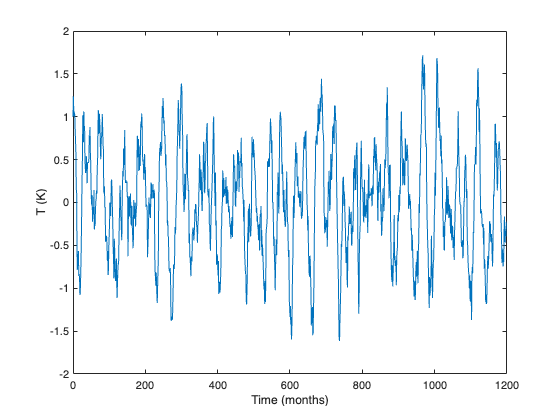

time=0:1:(N-1); % setting time coordinate 

figure;
plot(time,T_ro(:,1)) % plot first ensemble member solution of T 
xlabel("Time (months)")
ylabel("T (K)")

**Advanced Usage**

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM)`

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM, dt)`

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM, dt, saveat)`

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod)`

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod, EF)`

`[T_ro, h_ro, _] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod, EF, noise_custom)`

- Optional arguments allow for more control.

- Each additional argument gives more precise control over the solver.

- Refer to the previous section for details on each argument.

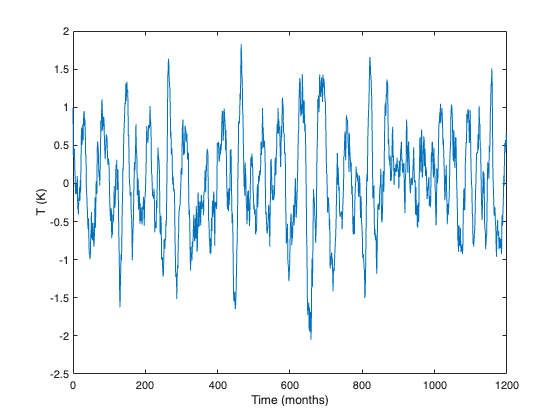

% Example 3-2. Solve RO with user-specified settings
[T_ro, h_ro] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod, EF, noise_custom); % solve RO 
time=0:1:(N-1); % setting time coordinate 

figure;
plot(time,T_ro(:,1)) % plot first ensemble member solution of T 
xlabel("Time (months)")
ylabel("T (K)")

**Analytical Solutions**

`[T_ref, h_ref, _] = RO_solver_analytic(par, IC, N, NE)`

`[T_ref, h_ref, _] = RO_solver_analytic(par, IC, N, NE, dt)`

`[T_ref, h_ref, _] = RO_solver_analytic(par, IC, N, NE, dt, saveat)`

`[T_ref, h_ref, _] = RO_solver_analytic(par, IC, N, NE, dt, saveat, savemethod)`

`[T_ref, h_ref, _] = RO_solver_analytic(par, IC, N, NE, dt, saveat, savemethod, noise_custom)`

- This function returns the **analytical solution** for the **linear RO system** without seasonality, using **white additive noise**. Its usage is structurally similar to `RO_solver`, but with the following key differences: `'NM'` (numerical method) and `'EF'` (external forcing) are **not required or accepted**.

- To ensure a **meaningful comparison** with the numerical solution from `RO_solver`, use the **same seed** for `noise_custom` in both simulations.

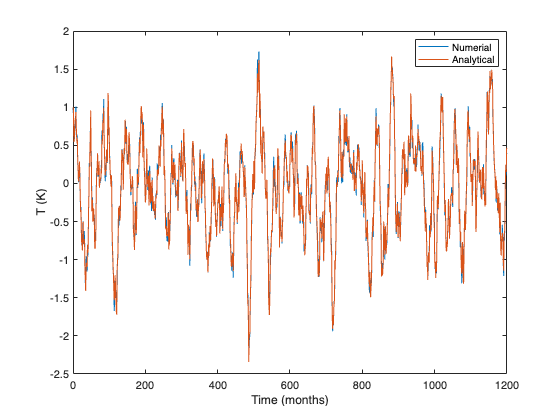

% Example 3-3. Compare numerical and analyticla solution 
noise_custom=999; % setting fixed noise value
[T_ro, h_ro] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod, EF, noise_custom); % solve RO numericallly
[T_ref, h_ref] = RO_solver_analytic(par, IC, N, NE, dt, saveat, savemethod, noise_custom); % solve RO analytically

time=0:1:(N-1); % setting time coordinate 

figure;
plot(time,T_ro(:,1))
hold on
plot(time,T_ref(:,1))
legend("Numerial","Analytical")
xlabel("Time (months)")
ylabel("T (K)")

`RO_std_ref = RO_std_analytic(par)`

- It returns the **theoretical standard deviations** of T and h for the **linear-white-additive** configuration based on the given parameter dictionary `par`.

`BWJ = RO_BWJ(par)`

- It computes the **BJ** and **Wyrtki** indices, where the real part (`{BWJ.real}`) corresponds to the BJ index and the imaginary part (`{BWJ.imag}`) corresponds to the Wyrtki index, based on the given parameter dictionary `par`.

% Example 3-4. Compare standard deviation of numerical and analytial solutions
[T_ref_std, h_ref_std] = RO_std_analytic(par); % calculate theoretical stnadard deviation

noise_custom=[];
[T_ro, h_ro] = RO_solver(par, IC, N, NE, NM, dt, saveat, savemethod, EF, noise_custom); % solve RO numericallly
T_ro_std_ens = std(T_ro(end,:),[],2); % ensemble-wise standard deviation at t=N (N=1200 months)
T_ro_std_tmp = mean(std(T_ro,[],1)); % multi-ensemble mean of standard deviation for entire simulation period


% Example 3-5. Calculate BWJ Index
BWJ = RO_BWJ(par); 

## 4.RO Parameter Fitting Setup

**Input T and h time series**

- `T and h are input timeseries used for the fitting `

- `T and h must be 1D time series arrays with a uniform time step`

**Specifiying RO Type**

These options define the RO model type used for fitting. 

The following example shows how to set the RO type as linear-white-additive RO for the fitting.

`par_option_T specifies the linear and nonlinear terms in dT/dt`

`par_option_h specifies the linear and nonlinear terms in dh/dt`

par_option_T=struct("R",1,"F1",1,"b_T",0,"c_T",0,"d_T",0); % specify types in dT/dt 
par_option_h=struct("F2",1,"epsilon",1,"b_h",0); % specify types in dh/dt 

- For values in `par_option_T` and `par_option_h`, allowed values:

- `0` — Do not estimate

- `1` — Estimate only the annual mean

- `3` — Estimate annual mean + annual seasonality

- `5` — Estimate annual mean + annual + semi-annual seasonality

`par_option_noise specifies the noise type `

par_option_noise=struct("T","white","h","white","T_type","additive"); % specify noise types 

- For values in �T and h, allowed values: 

- "`white`" — noise is white noise forcing

- "red" — noise is red noise forcing

- both T and h **must use the same noise type**; otherwise, an error is raised.

- For values in `T_type `

- `"additive" - T noise forcing is additive `

- `"multiplicative" - T noise forcing is multiplicative`

- `"multiplicative-H" - T noise forcing is Heaviside based-multiplicative noise`

**Advanced options (optional)**

- The following block sets additional **optional settings** for the RO parameter fitting

- The user can skip to specify these options. If the user doesn't specify these options, the RO parameter fitting runs with the default settings. 

`method_fitting specifies the parameter fitting method`

method_fitting="MLE";

- For values in method_fitting

- `"LR-F" - Linear regression using forward difference `

- `"LR-C" - Linear regression using central difference `

- `"LR-F-MAC" - Linear regression using forward difference with Moment Analytical Constraint (MAC) for parameter B `

- `"MLE" - Maximum Liklihood Estimation `

- `The default method depends on the RO type is specified. `

- `Details of fitting methods are documented in the manual and the paper`

`dt specifies time interval of input T and h time series in month (default = 1.0)`

dt = 1.0;

## 5. RO Parameter Fitting from Time Series

**Basic Usage**

`par_fitted = RO_fitting(T, h, par_option_T, par_option_h, par_option_noise)`

This is the simplest setup:

- `par_fitted is fitted RO parameters `

% Example 5-1. RO parameter fitting with default settings 
% using simulated T and h 
T_fitting = T_ro(:,1);
h_fitting = h_ro(:,1);
par_fitted = RO_fitting(T_fitting, h_fitting, par_option_T, par_option_h, par_option_noise);

Fitting Method: LR-F


**Advanced Usage**

`par_fitted = RO_fitting(T, h, par_option_T, par_option_h, par_option_noise, method_fitting)`

`par_fitted = RO_fitting(T, h, par_option_T, par_option_h, par_option_noise, method_fitting, dt)`

% Example 5-2. RO parameter fitting with user-specified settings
% using simulated T and h 
T_fitting = T_ro(:,1);
h_fitting = h_ro(:,1);
par_fitted = RO_fitting(T_fitting, h_fitting, par_option_T, par_option_h, par_option_noise, "MLE", 1.0);

Fitting Method: MLE


## **6. RO Parameter Fitting from Observation & Reproducing**

%% Load Observation T and h
fpath=pwd+"/Data/"+"XRO_indices_oras5.nc"; % file load path 
Tobs=ncread(fpath,'Nino34'); % load T (Nino 3.4 index)
hobs=ncread(fpath,'WWV'); % load h (equatorial mean thermocline depth) 
ncdisp(fpath)

Source:
           /Volumes/home/ENSO_Community_RO/Manuscript/CRO_Code_v0.0/Data/XRO_indices_oras5.nc
Format:
           netcdf4
Dimensions:
           time = 552
Variables:
    Nino34
           Size:       552x1
           Dimensions: time
           Datatype:   single
           Attributes:
                       standard_name      = 'Sea Surface temperature'
                       long_name          = "SST 5°S–5°N, 170°–120°W"
                       units              = 'C'
                       online_operation   = 'ave(x)'
                       interval_operation = 1200
                       interval_write     = 2678400
                       offline_operation  = 'ave(x)'
                       coordinates        = 'month'
    WWV   
           Size:       552x1
           Dimensions: time
           Datatype:   single
           Attributes:
                       standard_name      = 'Depth of 20C isotherm'
                       long_name          = "Hm: 5°S–5°N, 120°E–80°W"

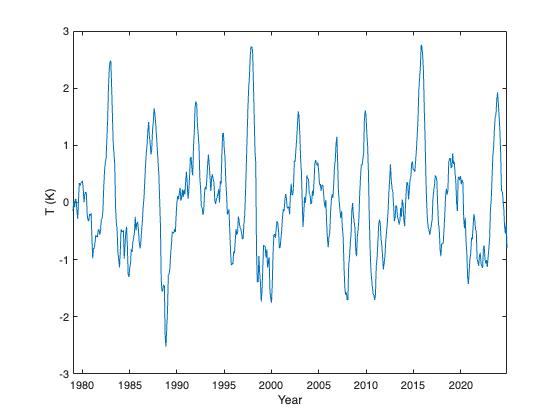

% Plot Observation T 
time=1979:(1/12):1979+46-1/12; % 1979 (Jan) - 2024 (Dec) 

figure;
plot(time,Tobs)
xlabel("Year")
ylabel("T (K)")
xlim([time(1) time(end)])

% Setting RO type
par_option_T=struct("R",5,"F1",5,"b_T",0,"c_T",0,"d_T",0);
par_option_h=struct("F2",5,"epsilon",5,"b_h",0);
par_option_noise=struct("T","red","h","red","T_type","additive");

% Parameter fitting using default options
par_fitted_obs=RO_fitting(Tobs,hobs,par_option_T,par_option_h,par_option_noise);

Fitting Method: LR-F


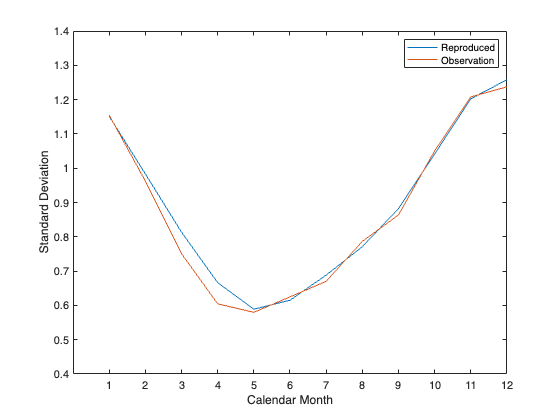

% Reproduce observion using the fitted parameters
IC=[Tobs(1);hobs(1)]; % initial condition of T (K) and h (m) 
N=length(Tobs); % simulation time (month) 
NE=1000; % number of ensemble 
NM="EH"; % numerical method of RO solver ("EH" and "EM") (optional input; default="EH") 
dt=1/30; % numerical time step (month) (optional input; default=0.1) 
saveat=1.0; % save interval of simulated T and h (month) (optional input; default=1.0)
savemethod="mean"; % save method ("sampling" and "mean") (optional input, default="mean")
EF={0.0;0.0}; % external forcing (optional input; deafult={0.0 0.0})
noise_custom=[]; % customized noise for solving RO (optional input; default=[]) 

% Solve RO 
[Tobs_re,hobs_re]=RO_solver(par_fitted_obs,IC,N,NE,NM,dt,saveat,savemethod,EF,noise_custom); % output: T ([time x ensemble]), h ([time x ensemble])

% Compare monthly standard deviations
Tobs_mon_std=func_mon_std(Tobs,1.0); % calculate observation monthly standard deviation 

for i=1:size(Tobs_re,2)
    Tobs_re_std(:,i)=func_mon_std(Tobs_re(:,i),saveat); % calculate reproduced monthly standard deviation 
end 
Tobs_re_std_mean=mean(Tobs_re_std,2); % calculate ensemble mean monthly standard deviation

% Plot monthly standard deviation
figure; 
plot(1:1:12,Tobs_re_std_mean)
hold on
plot(1:1:12/saveat,Tobs_mon_std)
xticks(1:1:12)
xlabel("Calendar Month")
ylabel("Standard Deviation")
legend("Reproduced","Observation")
ylim([0.4 1.4])

## **7. RO Parameter from the Parameter Library & Solve**

Users can load a set of pre-fitted RO model parameters from the CRO parameter library. The library contains parameters estimated from observations and CMIP6 historical simulations for different RO types. 

**Usage**

`par = RO_solver(data_name, RO_type)`

**Options**

data_name specifies the data source of the parameter set. The library includes one observational dataset and 48 CMIP6 historical simulations. 

RO_type specifies the RO equation type used in the parameter fitting. 

The full list of data_name and RO_type options can be found in the CRO manual.

The example below shows how to load parameter values for a Linear-White-Additive type RO equation. 

% Example 7-1. ORAS5 reanalysis (1958-2022) 
data_name="ORAS5"; % data type of fitted parameters 
RO_type="Linear-White-Additive"; % RO type of fitted parameters 
par=par_load(data_name,RO_type); 

% Example 7-2. CMIP6 CESM2 historial simulation 
data_name="CMIP6-historical-8"; % data type of fitted parameters 
RO_type="Linear-White-Additive"; % RO type of fitted parameters 
par=par_load(data_name,RO_type); 

% Example 7-3. All 48 CMIP6 historial simulations in the libarary 
data_name="CMIP6-historical-all"; % data type of fitted parameters 
RO_type="Linear-White-Additive"; % RO type of fitted parameters 
par=par_load(data_name,RO_type); 

**Applications**

Using the library, users can quickly set up parameters for CRO solving. 

The example below shows how to load the parameter set fitted for the CMIP6 CESM2 historical simulation with the Seasonal-Linear-White-Additive type, and solve �it. 

% Example 7-4. Solving RO using CMIP6 historical CESM2 parameter
data_name="CMIP6-historical-8"; % data type of fitted parameters 
RO_type="Seasonal-Linear-White-Additive"; % RO type of fitted parameters 
par=par_load(data_name,RO_type); 

IC=[1.0;0.0]; % Initial condition for T (K) and h (m) 
N=12*(1000); % Simulation length (month)
NE=1; % Number of ensemble members 

[T_CESM2, h_CESM2] = RO_solver(par, IC, N, NE); 
time=0:1:(N-1); % setting time coordinate 

figure;
plot(time,T_CESM2(:,1)) % plot first ensemble member solution of T 
xlabel("Time (months)")
ylabel("T (K)")